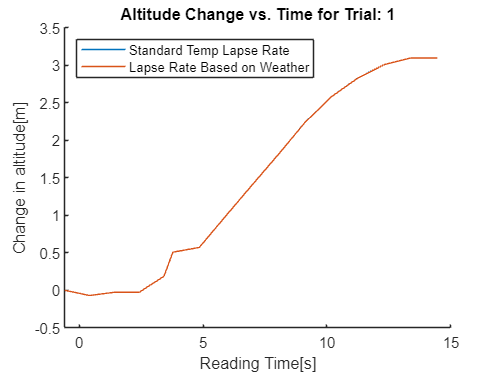

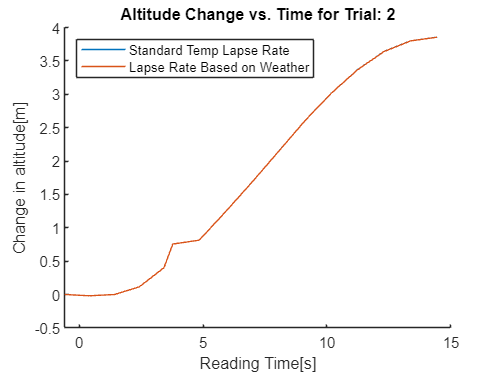

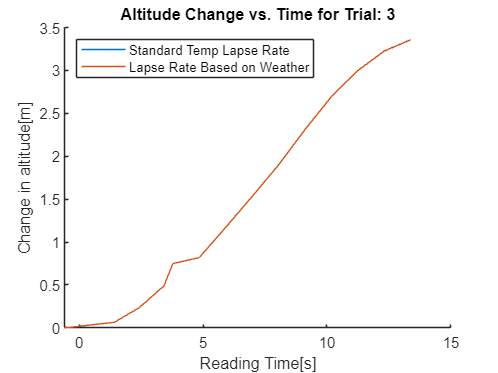

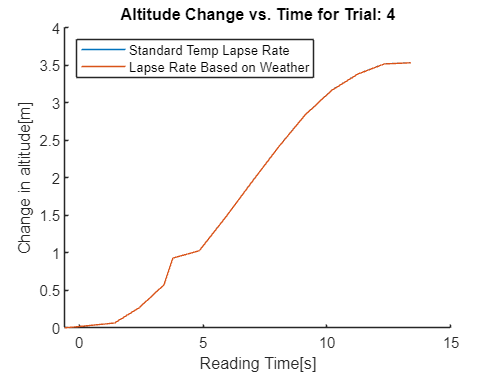

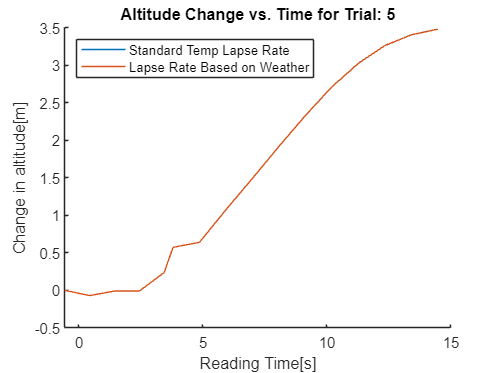

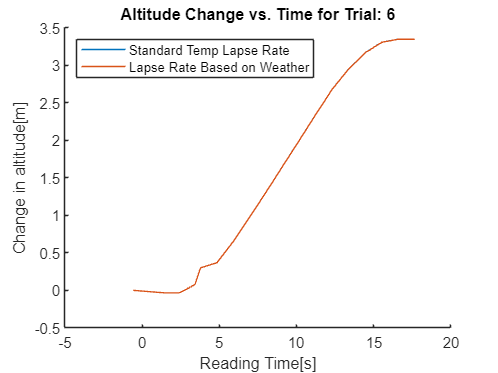

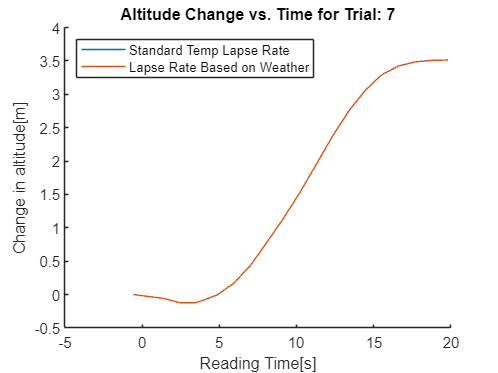

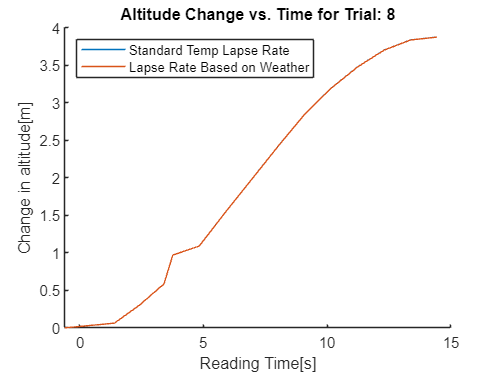

clear all
weatherFileN="STU-60-20241124144111.csv";
files=struct2table(dir);
fileList=files.name(3:33);%Will have to adjust based on folder
%COVERED STAIRS
% fileList={
%     'Pressure 2024-11-04 15-40-25.xls',...
%     'Pressure 2024-11-04 15-41-30.xls',...
%     'Pressure 2024-11-04 15-42-39.xls',...
%     'Pressure 2024-11-04 15-43-49.xls',...
%     'Pressure 2024-11-04 15-44-55.xls',...
%     'Pressure 2024-11-04 15-46-14.xls',...
%     'Pressure 2024-11-04 15-47-44.xls',...
%     'Pressure 2024-11-04 15-49-07.xls',...
%     'Pressure 2024-11-04 15-50-24.xls',...
%     'Pressure 2024-11-04 15-51-54.xls',...
%     'Pressure 2024-11-04 15-53-12.xls',...
%     'Pressure 2024-11-04 15-54-28.xls',...
%     'Pressure 2024-11-04 15-55-48.xls',...
%     'Pressure 2024-11-04 15-57-06.xls'......
%     };
%%%%%%%%%%%%%%%%%%%%


approxGroundTruth=3.5306;%139 in

%%%%%%%%%%%%%%%%%%%
endAlts=zeros(length(fileList),1);
for i=1:length(fileList)
    endAlts(i)=totalAltChange(string(fileList(i)),weatherFileN,true,i*100);
end


%STATS SECTION IDEALLY WANT 30+ trials so central limit theroy is more
%applicable
meanAltGain=mean(endAlts);
stdAltGain=std(endAlts);
approxErrors=approxGroundTruth-endAlts;
meanError=mean(approxErrors);
stdErrors=std(approxErrors);
kstest(approxErrors,'CDF', makedist('Normal', 'mu', meanError, 'sigma', stdErrors))

ans = logical
   0


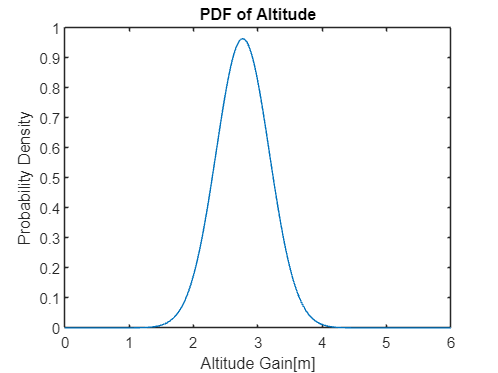

errorXvalues=[-3*stdErrors+meanError:.01:3*stdErrors+meanError];
dispXValues=[0:.01:6];
figure(111)
yAlt=normpdf(dispXValues,meanAltGain,stdAltGain);
plot(dispXValues,yAlt)
xlabel("Altitude Gain[m]")
ylabel("Probability Density")
title("PDF of Altitude")

disp("The average Change in Altitude is: "+num2str(meanAltGain)+"m")

The average Change in Altitude is: 2.7657m


disp("The standard deviation of the change in altitude is: "+num2str(stdAltGain)+"m")

The standard deviation of the change in altitude is: 0.41437m


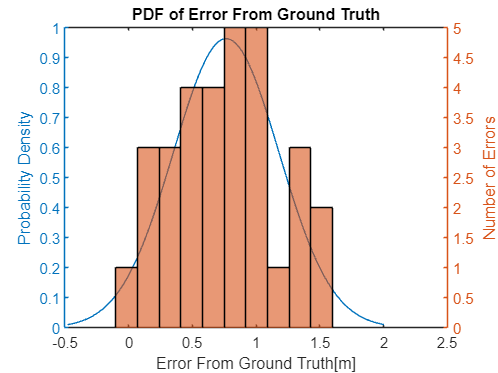

figure(112)
yErr=normpdf(errorXvalues,meanError,stdErrors);
yyaxis left
plot(errorXvalues,yErr)
ylabel("Probability Density")
hold on
yyaxis right
histogram(approxErrors,10)
xlabel("Error From Ground Truth[m]")
ylabel("Number of Errors")
title("PDF of Error From Ground Truth")

disp("The average error is: "+num2str(meanError)+"m")

The average error is: 0.76494m


disp("The standard deviation of the error is: "+num2str(stdErrors)+"m")

The standard deviation of the error is: 0.41437m


function averageEndAlt=totalAltChange(filename,weatherFileN,plotT,figNum)
    weatherData=readtable(weatherFileN);%Weather Data for Day measurment taken
    data=readtable(filename);%Read Data
    pressures=data.Pressure_hPa_*100;%pressures from phone barometer in Pa
    pressureTimes=data.Time_s_;%Times since start of pressure measurments
    [groundTemp,groundPressure,lbArr]=getWeatherForMeasurment(filename,pressureTimes,weatherData);
    lb=-.0065*ones(length(pressures),1);%Standard temperature lapse rate
    R=8.31432;%universal gas constant
    g=9.80665;%Gravity
    M=0.0289644;%Molar mass of air
    dAlt=changeInAltitude(pressures,groundTemp,lb,R,g,M);
    dAtl2=changeInAltitude(pressures,groundTemp,lbArr,R,g,M);
    if plotT
        figure(figNum)
        hold on
        plot(pressureTimes,dAlt)
        plot(pressureTimes,dAtl2)
        xlabel("Reading Time[s]")
        ylabel("Change in altitude[m]")
        title("Altitude Change vs. Time for Trial: "+num2str(figNum/100))
        legend("Standard Temp Lapse Rate","Lapse Rate Based on Weather",location='northwest')
        hold off
    end
    averageEndAlt=mean(dAlt(end-10:end));
    
end
function deltaAltitudeArray=changeInAltitude(pressure,temperature,lb,R,g,M)
    deltaAltitudeArray=zeros(length(pressure),1);
    p0=pressure(1);
    for i=1:length(temperature)
        deltaAltitudeArray(i)=calculateAlt(p0,pressure(i),0,temperature(i),lb(i),R,g,M);

    end

end

function altitude=calculateAlt(p0,p1,h0,temp,lb,R,g,M)
    %altitude=h0+temp/lb*((p1/p0)^(-R*lb/(g*M))-1);
    altitude=h0+temp/lb*(1-(p1/p0)^(R*lb/(g*M)));
end

function [ambientTemp,ambientPressure,lbMat]=getWeatherForMeasurment(filename,readingTimes,weatherData)
    spaceIndex=strfind(filename," ");%get indecies for spaces in file name
    initTimeStr=string(extractBetween(filename, spaceIndex(end)+1, strfind(filename,".")-1));%Get End time of Measurments
    hour=str2num(extractBefore(initTimeStr,3))*60*60;
    minit=str2num(extractBetween(initTimeStr,4,5))*60;
    sec=str2num(extractAfter(initTimeStr,6));
    endTime=hour+minit+sec;
    startTime=endTime-readingTimes(end);
    ambientPressure=zeros(length(readingTimes),1);
    ambientTemp=zeros(length(readingTimes),1);
    lbMat=zeros(length(readingTimes),1);
    for i=1:length(readingTimes)
        timeFormatted=secondToTime(startTime+readingTimes(i));
        [closestTime, cIndex]=min(abs(weatherData.Time-timeFormatted));
        ambientTemp(i)=(weatherData.Temp__F_(cIndex)-32)*5/9+273.15;
        ambientPressure(i)=weatherData.Pressure_mb_(cIndex)*100;
        lbMat(i)=(((weatherData.Temp10m__F_(cIndex)-32)*5/9+273.15)-((weatherData.Temp2m__F_(cIndex)-32)*5/9+273.15))/(10-2);
    end

end

function closestMin=secondToTime(totalSec)
    h=floor(totalSec / 3600);
    m=floor(mod(totalSec, 3600) / 60);
    s=mod(totalSec, 60);
    closestMin=100*h+m+round(s/60);
end
